TrendTrading_WFA_MainScript

Preparation

clear
    
tic

Read data

load TrendTrading.mat % IndexTT PriceTTFullRaw VolumeTTFullRaw
% IndexTT ;
% PriceTTFullRaw ;
% VolumesTTFullRaw = VolumeTTFullRaw ;

Clean data

PricesTTFull = fillmissing (PricesTTFullRaw, "previous") ;
PricesTTFull = fillmissing (PricesTTFull, "next") ;

VolumesTTFullRawVars = VolumesTTFullRaw.Variables ;
VolumesTTFullRawVarsIdx = VolumesTTFullRawVars < 100';
VolumesTTFullRawVars (VolumesTTFullRawVarsIdx) = NaN ;
VolumesTTFullRaw.Variables = VolumesTTFullRawVars ;
VolumesTTFull = fillmissing (VolumesTTFullRaw, "previous") ;


Split data into number of steps and data index

TimeColumn = PricesTTFull.Time ;

% Start and end date of the backtest period
% DStringStartdate = '05-Jan-2015' ;
DStringEnddate = '30-Dec-2020'

DStringEnddate = '30-Dec-2020'


% Number of step (days) per train set and test set
NumStepTrainSet = 252*3 ; 
NumStepTestSet = 22*3 ;

% Number of train & test set pair
NumTrainTestSet = 4 ;

% bStartdate = datetime (DStringStartdate, "InputFormat", "dd-MMM-uuuu")
% bStartdateIdx = find (TimeColumn == bStartdate) 

bEnddate = datetime (DStringEnddate, "InputFormat", "dd-MMM-uuuu")

bEnddate = datetime
   30-Dec-2020


bEnddateIdx = find (TimeColumn == bEnddate) 

bEnddateIdx = 2732


bStartdateIdx = bEnddateIdx - NumTrainTestSet*NumStepTestSet - NumStepTrainSet  %NumTrainTestSet*(NumStepTrainSet+NumStepTestSet) 

bStartdateIdx = 1712

bStartdate = TimeColumn(bStartdateIdx)

bStartdate = datetime
   22-Dec-2016



PricesTTbtDataset = PricesTTFull (bStartdateIdx:bEnddateIdx, :) ;
VolumesTTbtDataset = VolumesTTFull (bStartdateIdx:bEnddateIdx, :) ;
dailyRetTTbtDataset = tick2ret(PricesTTbtDataset) ;


Split data into IST and OST then optimize parameters per Step

nvars = 7 ;
% Preallocate variables
xOptimized = zeros (NumTrainTestSet, nvars) ; % preallocate xoptimized 
StartTestsetIdx = bStartdateIdx + NumStepTrainSet;
EndTestsetIdx = StartTestsetIdx + NumTrainTestSet*NumStepTestSet +3; % 3 is an adjustment from backtesting
T = TimeColumn (StartTestsetIdx:EndTestsetIdx,:)

T = 268×1 datetime array
   26-Nov-2019
   27-Nov-2019
   28-Nov-2019
   29-Nov-2019
   02-Dec-2019
   03-Dec-2019
   04-Dec-2019
   05-Dec-2019
   06-Dec-2019
   09-Dec-2019
   10-Dec-2019
   11-Dec-2019
   12-Dec-2019
   13-Dec-2019
   16-Dec-2019
   17-Dec-2019
   18-Dec-2019
   19-Dec-2019
   20-Dec-2019
   23-Dec-2019
   26-Dec-2019
   27-Dec-2019
   30-Dec-2019
   02-Jan-2020
   03-Jan-2020
   06-Jan-2020
   07-Jan-2020
   08-Jan-2020
   09-Jan-2020
   10-Jan-2020


sz = [size(T,1) 1] ;
varTypes = {'double'} ;
dailyRetTestset = timetable('Size',sz,'VariableTypes',varTypes,'RowTimes',T) ;

LiquidSurgAvgLagDays = 200 ; % Largest start IDX setrics in signal strategy backtest


% for i = 1:NumTrainTestSet
     i = 2

i = 2

    % Train & test set for each i
    % Train set idx i
    TrainsetStartdateIdxi = i 

TrainsetStartdateIdxi = 2

    TrainsetEnddateIdxi = TrainsetStartdateIdxi + NumStepTrainSet

TrainsetEnddateIdxi = 758

    
    % Test set idx i
    TestsetStartdateIdxi = TrainsetEnddateIdxi

TestsetStartdateIdxi = 758

    TestsetEnddateIdxi = TestsetStartdateIdxi + NumStepTestSet

TestsetEnddateIdxi = 824

    
    % Train dataset i
    PricesTTtrainDSi = PricesTTbtDataset (TrainsetStartdateIdxi:TrainsetEnddateIdxi, :)

PricesTTtrainDSi = 757×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS     AHAP     AGRS     AGRO     AGII    AGAR    ADRO    ADMG    ADMF    ADHI    ADES    ACST    ACES    ABMM    ABDA    ABBA    AALI     AMAG    ALTO    ALMI    ALKA     ALDO     AKSI    AKRA    AKPI    AKKU    DLTA

    VolumesTTtrainDSi = VolumesTTbtDataset (TrainsetStartdateIdxi:TrainsetEnddateIdxi, :)

VolumesTTtrainDSi = 757×665 timetable
       Time           ANTM       ANJT    ANDI       AMRT       AMOR      AMIN       AMFG     AMAR    AMAN       AISA       AIMS        AHAP         AGRS          AGRO          AGII       AGAR       ADRO          ADMG         ADMF          ADHI       ADES        ACST          ACES       ABMM     ABDA       ABBA          AALI          AMAG          ALTO       ALMI     ALKA     ALDO    AKSI

    
    % Test dataset i
    PricesTTtestDSi = PricesTTbtDataset (TestsetStartdateIdxi-LiquidSurgAvgLagDays:TestsetEnddateIdxi, :)

PricesTTtestDSi = 267×665 timetable
       Time        ANTM    ANJT    ANDI    AMRT    AMOR    AMIN    AMFG    AMAR    AMAN    AISA    AIMS    AHAP    AGRS    AGRO    AGII    AGAR    ADRO    ADMG    ADMF     ADHI    ADES    ACST    ACES    ABMM    ABDA    ABBA    AALI     AMAG    ALTO    ALMI    ALKA    ALDO    AKSI    AKRA    AKPI    AKKU    DLTA    <

    VolumesTTtestDSi = VolumesTTbtDataset (TestsetStartdateIdxi-LiquidSurgAvgLagDays, :)

VolumesTTtestDSi = 1×665 timetable
       Time           ANTM         ANJT         ANDI         AMRT       AMOR      AMIN       AMFG    AMAR    AMAN       AISA       AIMS     AHAP      AGRS          AGRO       AGII     AGAR       ADRO          ADMG       ADMF        ADHI       ADES       ACST          ACES       ABMM    ABDA       ABBA         AALI       AMAG     ALTO      ALMI       ALKA       ALDO       AKSI        <

    
    % Optimize Trainset
    % surrogateopt for expensive optim problems
    % Assign IST dataset
    PricesISTi = PricesTTtrainDSi ;
    VolumesISTi = VolumesTTtrainDSi ;
    
    NumFunctionEvaluations = 70 ; % Set different value for development or live stage
    options = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
        "ConstraintTolerance",1e-2,'UseParallel', true, ...
        'MaxFunctionEvaluations', NumFunctionEvaluations);

    fun = @(x) TrendTradingFcnMultiVarSharpe (x, PricesISTi, VolumesISTi) ;
    nvars = 7 ;
    lb = [1	1 -50  1	1	-50 -50] ;
    ub = [10^15 10^15	80 10^15 10^15 80 80 ] ;
    intcon = 1:nvars ;

    [xSharpeSur,fvalm,~,~,pop] = surrogateopt(fun,lb,ub,intcon,options);

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


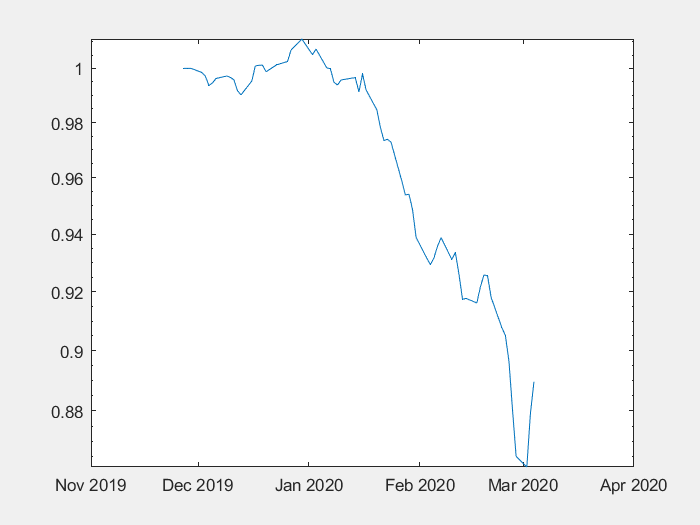

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn              -0.11038    
    SharpeRatio              -0.28073    
    Volatility              0.0061918    
    AverageTurnover          0.013364    
    MaxTurnover                   0.5    
    AverageReturn          -0.0017252    
    MaxDrawdown               0.14767    
    AverageBuyCost             3.0868    
    AverageSellCost            1.1306    


EndCumSumVar = -0.8896

TradingPeriod = 0.2678

CAGR = 0.3539

SharpeRatio = 4.4387

Sortino = 5.0948

Elapsed time is 1.300920 seconds.


dailyRetTestseti = 67×1 timetable
       Time        TrendTradeStrategy
    ___________    __________________

    27-Nov-2019                 0    
    28-Nov-2019                 0    
    29-Nov-2019                 0    
    02-Dec-2019           -0.0015    
    03-Dec-2019        -0.0013299    
    04-Dec-2019        -0.0035795    
    05-Dec-2019        0.00097368    
    06-Dec-2019         0.0016806    
    09-Dec-2019        0.00093643    
    10-Dec-2019       -0.00054383    
    11-Dec-2019       -0.00086097    
    12-Dec-2019        -0.0041046    
    13-Dec-2019        -0.0015164    
    16-Dec-2019          0.005119    
    17-Dec-2019         0.0056949 

    xSharpeSurOptimizedi = xSharpeSur ;
    
    % Save xOptimized per at each i cycle for each trainset )i row, size(x) column
    xOptimized (i,:) = xSharpeSurOptimizedi ;
    
    % Apply xOptimized to testset at each i cycle 
    % Assign OST dataset
    PricesOSTi = PricesTTtestDSi ; 
    VolumesOSTi = VolumesTTtestDSi ; 
    xOptimizedOSTi = xOptimized (i,:) ;
    
    dailyRetTestseti = TrendTradingFcnMultiVarDailyRetGraph (xOptimizedOSTi, ...
        PricesOSTi, VolumesOSTi)

    
    rowLengthi = size (dailyRetTestseti,1) ;
    dailyRetTestset (max(i,rowLengthi*(i-1))+1:rowLengthi*i, :) = dailyRetTestseti ;

To assign to or create a variable in a table, the number of rows must match the height of the table.

        
    % Plot test set backtest results
    dailyRetTestsetProgress = dailyRetTestset (1:i*rowLengthi, :) ;
    PortfolioValueTestSet = ret2tick (dailyRetTestsetProgress) ;
    plot (PortfolioValueTestSet.Time, PortfolioValueTestSet.Variables)

% end

% Delete the 1st row zeros
 xOptimized (1,:) = [] ;
 

Save the xOptimized

 save ('TrendTradingWFA.mat', 'xOptimized', 'PricesTTFullRaw', 'VolumesTTFullRaw')

Close

toc